# 統計解析(2要因分散分析)

目標：MMNが起きているチャンネルを探し，条件間で比較する。

１．データを扱いやすいように変形させる。

data_aveは，３次元目にstd条件とdev条件があるので，

(dev条件) - (std条件)とデータを変形する。

２．さらに，このときの波形を観察してどの期間にMMNが発生してそうか，「MMNが出ていそうな時間窓」を決める。

３．その時間窓の平均振幅が 0 と異なるか評価する（1標本t検定）。

４．有意だったチャンネルで deviant 3条件（1010/1030/1050 Hz）を比較（反復測定ANOVA）。

## １．データを扱いやすいように変形させる。

MMNの大きさを条件毎に比較したいのでdeviant条件からstandard条件を引く。

変数は，data_av % (ch, time, [std or var],[1010 or 1030 , 1050],par)

を使えばよい。

data_dif=squeeze(data_ave(:,:,2,:,:)-data_ave(:,:,1,:,:)); % MMN成分の抽出

## ２.1. さらに，このときの波形を観察してどの期間にMMNが発生してそうか，時間帯を調べる。

チャンネル毎にMMN（deviant - standard）の平均波形を書いてください。006で書いた平均波形と一致することを確認してください。

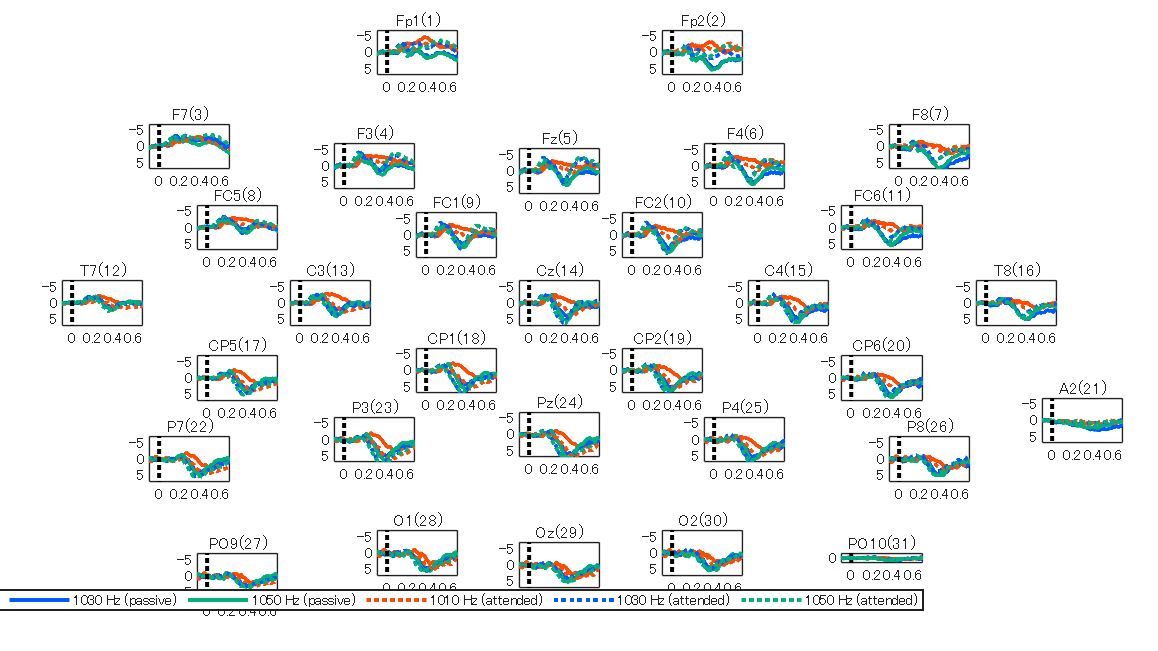

fs = 1000; % サンプリング周波数
N=size(data_dif,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
load('EEG_locs_new.mat');

sz = get(0, 'ScreenSize');

x=linspace(-0.1,(N-100)/fs,N);

figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure
for chl=1:size(sloc,1)
    subplot('position',[sloc(chl,1) sloc(chl,2) 0.07 0.07])
    hold on
    % passive condition (reading)
    h(1) = plot(x, mean(data_dif(chl,:,1,end-6:end),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2);
    h(2) = plot(x, mean(data_dif(chl,:,2,end-6:end),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2);
    h(3) = plot(x, mean(data_dif(chl,:,3,end-6:end),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2);
    % attended condition
    h(4) = plot(x, mean(data_dif(chl,:,1,1:end-7),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2,'LineStyle',':');
    h(5) = plot(x, mean(data_dif(chl,:,2,1:end-7),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2,'LineStyle',':');
    h(6) = plot(x, mean(data_dif(chl,:,3,1:end-7),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2,'LineStyle',':');
    
    axis('ij')

    ymx=7;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
%     title(ch)
    xlim([-0.1 0.7])
    ylim([-ymx ymx])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)
end
legend(h, ...
 {'1010 Hz (passive)', '1030 Hz (passive)', '1050 Hz (passive)', ...
  '1010 Hz (attended)', '1030 Hz (attended)', '1050 Hz (attended)'}, ...
 'Location','southoutside','Orientation','horizontal');
makeSubplotsClickable();

全チャンネル表示からめぼしいチャンネルを選択してfigureを描いてください。

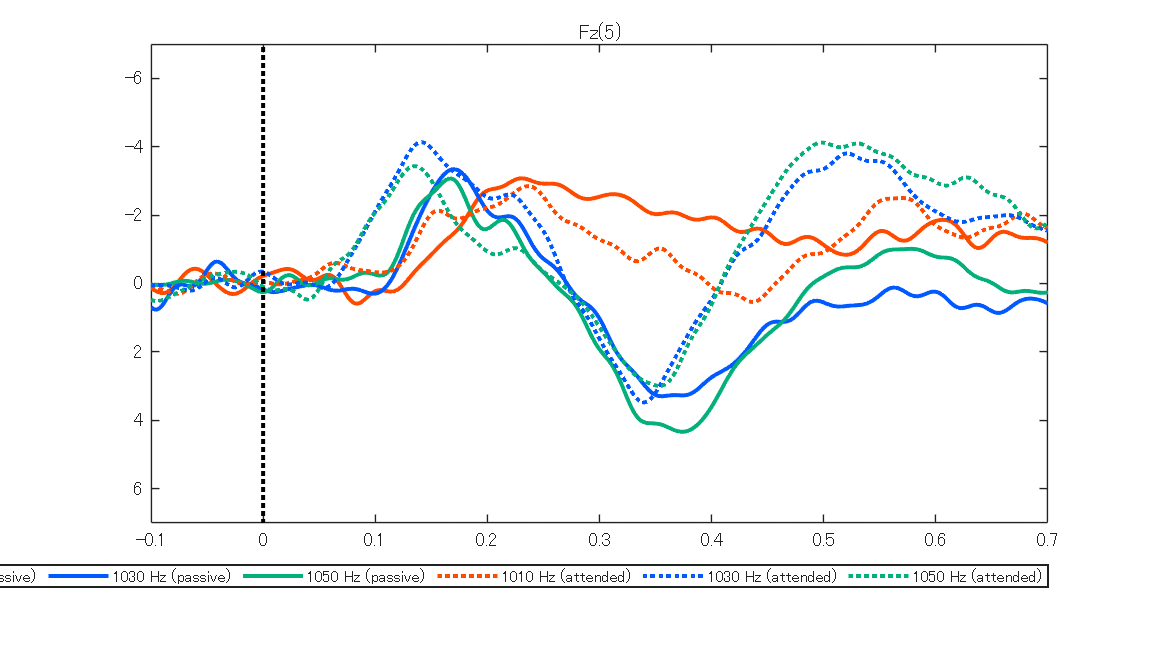

fs = 1000; % サンプリング周波数
N=size(data_dif,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
x=linspace(-0.1,(N-100)/fs,N);

sz = get(0, 'ScreenSize');
figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure
for chl=5
%     subplot('position',[sloc(ch,1) sloc(ch,2) 0.07 0.07])
    hold on
    % passive condition (reading)
    h(1) = plot(x, mean(data_dif(chl,:,1,end-6:end),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2);
    h(2) = plot(x, mean(data_dif(chl,:,2,end-6:end),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2);
    h(3) = plot(x, mean(data_dif(chl,:,3,end-6:end),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2);
    % attended condition
    h(4) = plot(x, mean(data_dif(chl,:,1,1:end-7),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2,'LineStyle',':');
    h(5) = plot(x, mean(data_dif(chl,:,2,1:end-7),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2,'LineStyle',':');
    h(6) = plot(x, mean(data_dif(chl,:,3,1:end-7),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2,'LineStyle',':');
    axis('ij')

    ymx=7;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
%     title(ch)
    xlim([-0.1 0.7])
    ylim([-ymx ymx])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)
end
legend(h, ...
 {'1010 Hz (passive)', '1030 Hz (passive)', '1050 Hz (passive)', ...
  '1010 Hz (attended)', '1030 Hz (attended)', '1050 Hz (attended)'}, ...
 'Location','southoutside','Orientation','horizontal');

全チャンネル表示からめぼしいチャンネルを選択してfigureを描いてください。

SNが悪いなと思えばチャンネルを平均しても良い。

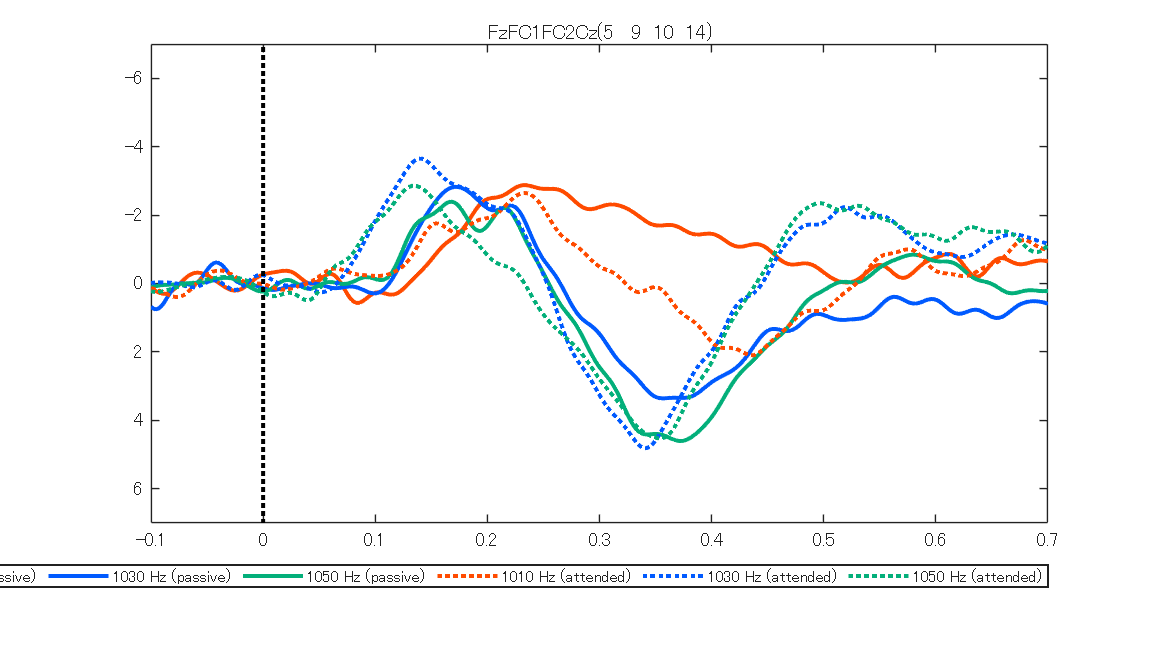

fs = 1000; % サンプリング周波数
N=size(data_dif,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
x=linspace(-0.1,(N-100)/fs,N);

sz = get(0, 'ScreenSize');
figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure
chl=[5 9 10 14];
%     subplot('position',[sloc(ch,1) sloc(ch,2) 0.07 0.07])
    hold on
    % passive condition (reading)
    h(1) = plot(x, mean(mean(data_dif(chl,:,1,end-6:end),1,'omitnan'),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2);
    h(2) = plot(x, mean(mean(data_dif(chl,:,2,end-6:end),1,'omitnan'),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2);
    h(3) = plot(x, mean(mean(data_dif(chl,:,3,end-6:end),1,'omitnan'),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2);
    % attended condition
    h(4) = plot(x, mean(mean(data_dif(chl,:,1,1:end-7),1,'omitnan'),4,'omitnan'), 'Color', [255  75   0]/255, 'LineWidth',2,'LineStyle',':');
    h(5) = plot(x, mean(mean(data_dif(chl,:,2,1:end-7),1,'omitnan'),4,'omitnan'), 'Color', [  0  90 255]/255, 'LineWidth',2,'LineStyle',':');
    h(6) = plot(x, mean(mean(data_dif(chl,:,3,1:end-7),1,'omitnan'),4,'omitnan'), 'Color', [  3 175 122]/255, 'LineWidth',2,'LineStyle',':');
    axis('ij')

    ymx=7;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
%     title(ch)
    xlim([-0.1 0.7])
    ylim([-ymx ymx])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)

legend(h, ...
 {'1010 Hz (passive)', '1030 Hz (passive)', '1050 Hz (passive)', ...
  '1010 Hz (attended)', '1030 Hz (attended)', '1050 Hz (attended)'}, ...
 'Location','southoutside','Orientation','horizontal');

## 2.2.　期間の定義

自分が思う期間を定義してください。データを参照または先行研究を参考に

いまは適当に100-150m秒とすると，秒→data pointに変更する。(+100points)

mmn_amp = squeeze(mean(data_dif(:,201:250,:,:,:),2,"omitnan")); % ←期間の決定（今は適当）
% size data_dif (31,3,12) (ch,freq,part)

## ３．その期間のamplitudeが０ではないことを統計学的に評価する（t検定）。

% passive condition (reading)
[~,p1,~,stats1] = ttest(permute(mmn_amp(:,:,end-6:end),[3 1 2])); 
% attended condition
[~,p2,~,stats2] = ttest(permute(mmn_amp(:,:,1:end-7),[3 1 2])); 

### t検定の結果を表示（t-map）

1010, 1030 , 1050条件ごとに，チャンネル位置でｔ値をカラーマップ（グラデーション）で表示します，

ただし，ｐ＜0.05の有意のチャンネルだけ表示，ｐ＞0.05のチャンネルはｔ値を０とします）

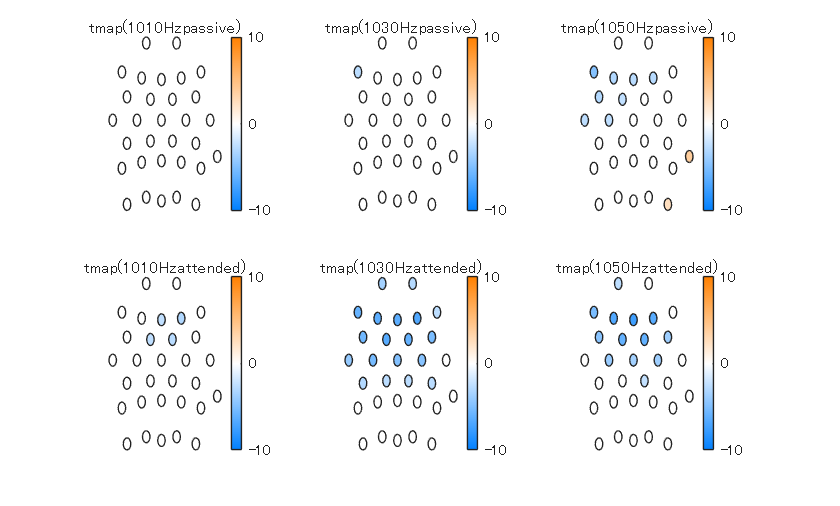

figure
hold on
amp=10;
thr=0.05;

devname = {'1010Hz','1030Hz','1050Hz'};
attname ={'passive','attended'};

% passive condition (reading)
for dev = 1:3
    subplot(2,3,dev)
    Map=squeeze(stats1.tstat(:,:,dev)); %size(1, 31, 3)(1, chl, [1010, 1030 , 1050]);
    Map(squeeze(p1(:,:,dev)>thr))=0; % p>0.05は0にする
    drawPatch34rwb(sloc,Map(:,:),0.03,[-amp amp]);
    colorbar('Ticks',[0, 0.5,1],...
        'TickLabels',{-amp 0 amp})
    axis tight;
    axis off;
    title(['tmap(' devname{dev} 'passive)'])
end

% attended condition

for dev = 1:3
    subplot(2,3,3+dev)
    Map=squeeze(stats2.tstat(:,:,dev)); %size(1, 31, 3)(1, chl, [1010, 1030 , 1050]);
    Map(squeeze(p2(:,:,dev)>thr))=0; % p>0.05は0にする
    drawPatch34rwb(sloc,Map(:,:),0.03,[-amp amp]);
    colorbar('Ticks',[0, 0.5,1],...
        'TickLabels',{-amp 0 amp})
    axis tight;
    axis off;
    title(['tmap(' devname{dev} 'attended)'])
end

## ４．t検定で有意になったチャンネルにおいて，３条件（deviant）をanovaで比較する。

## 4.1.1. データの様子（分布）を見てみる(1chl)。

全員分のデータを見てみよう

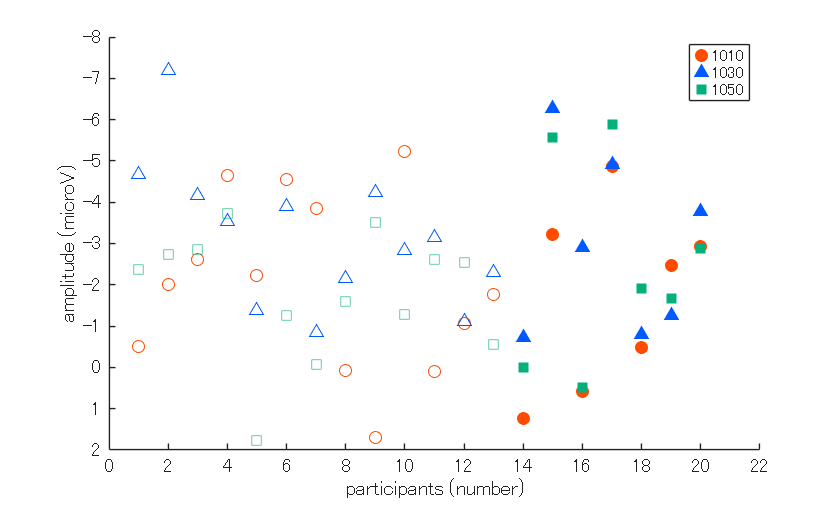

chl = 5; % 例：t-map を見て「有意」チャンネルを選ぶ
nP = size(mmn_amp,3);
figure
hold on
% passive condition (reading)
scatter(14:20, squeeze(mmn_amp(chl,1,end-6:end)), [],'MarkerEdgeColor', [255  75   0]/255,'Marker','o','MarkerFaceColor',[255  75   0]/255)
scatter(14:20, squeeze(mmn_amp(chl,2,end-6:end)), [],'MarkerEdgeColor', [  0  90 255]/255,'Marker','^','MarkerFaceColor',[  0  90 255]/255)
scatter(14:20, squeeze(mmn_amp(chl,3,end-6:end)), [],'MarkerEdgeColor', [  3 175 122]/255,'Marker','s','MarkerFaceColor',[  3 175 122]/255)

% attended condition
scatter(1:13, squeeze(mmn_amp(chl,1,1:end-7)), [],'MarkerEdgeColor', [255  75   0]/255,'Marker','o')
scatter(1:13, squeeze(mmn_amp(chl,2,1:end-7)), [],'MarkerEdgeColor', [  0  90 255]/255,'Marker','^')
scatter(1:13, squeeze(mmn_amp(chl,3,1:end-7)), [],'MarkerEdgeColor', [  3 175 122]/255,'Marker','s')

axis('ij')
xlabel(['participants (number)'])
ylabel('amplitude (microV)')
xlim([0, 22])
% ylim([80 105])
legend('1010','1030','1050','Location','best')

## 4.1.2. データの様子（分布）を見てみる(chl平均)。

全員分のデータを見てみよう

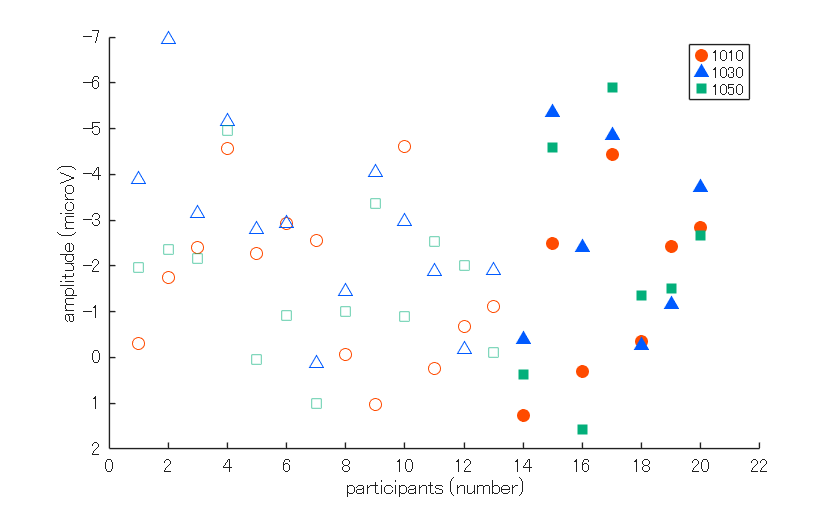

chl=[5 9 10 14];
nP = size(mmn_amp,3);
figure
hold on
% passive condition (reading)
scatter(14:20, squeeze(mean(mmn_amp(chl,1,end-6:end),1,'omitnan')), [],'MarkerEdgeColor', [255  75   0]/255,'Marker','o','MarkerFaceColor',[255  75   0]/255)
scatter(14:20, squeeze(mean(mmn_amp(chl,2,end-6:end),1,'omitnan')), [],'MarkerEdgeColor', [  0  90 255]/255,'Marker','^','MarkerFaceColor',[  0  90 255]/255)
scatter(14:20, squeeze(mean(mmn_amp(chl,3,end-6:end),1,'omitnan')), [],'MarkerEdgeColor', [  3 175 122]/255,'Marker','s','MarkerFaceColor',[  3 175 122]/255)

% attended condition
scatter(1:13, squeeze(mean(mmn_amp(chl,1,1:end-7),1,'omitnan')), [],'MarkerEdgeColor', [255  75   0]/255,'Marker','o')
scatter(1:13, squeeze(mean(mmn_amp(chl,2,1:end-7),1,'omitnan')), [],'MarkerEdgeColor', [  0  90 255]/255,'Marker','^')
scatter(1:13, squeeze(mean(mmn_amp(chl,3,1:end-7),1,'omitnan')), [],'MarkerEdgeColor', [  3 175 122]/255,'Marker','s')

axis('ij')
xlabel(['participants (number)'])
ylabel('amplitude (microV)')
xlim([0, 22])
% ylim([80 105])
legend('1010','1030','1050','Location','best')

## 4.2. 伝統的な mixed ANOVA（混合2要因：被験者内×被験者間）。

- 被験者内：**Deviant（3水準）**

- 被験者間：**Attention（attended vs passive）**

- 従属変数：MMN振幅（チャンネルは `chl` 固定）

### 手順

- **wide形式**（各被験者 = 1行、deviant 3条件 = 3列）を作る

- `fitrm`（反復測定モデル）を当てる

- `ranova` で被験者内効果（Deviant）と交互作用（Deviant×Attention）

- `anova` で被験者間効果（Attention）

## 0) 被験者の選び方（7 vs 7 に揃える版）

現在の参加者はattendedが13名，passiveが7名なので，passiveの7名に揃えて比較することとします。

% chlの定義
chl=5; % 適当


rng(1);                % 今は再現性のため固定，数字を変更して参加者の組み合わせを変えてみる
idx_att_all = 1:13;    % attended候補
idx_pas     = 14:20;   % passive 7名

idx_att_sub = randsample(idx_att_all, 7);
idx_sel     = [idx_att_sub, idx_pas]; % 合計14名

Attention = [repmat("attended",7,1); repmat("passive",7,1)];
Attention = categorical(Attention);


## 1) wide形式データを作る（14×3）

各行=被験者、列=deviant(3条件)

Y = squeeze(mmn_amp(chl,:,idx_sel))';  % 期待：14 x 3 になるように転置
% 列の意味：(:,1)=deviant1, (:,2)=deviant2, (:,3)=deviant3

うまくいってるか確認：

size(Y)   % -> [14 3] を期待

ans =     14     3


## 2) fitrm 用のテーブルを作る

Twide = table(Attention, Y(:,1), Y(:,2), Y(:,3), ...
    'VariableNames', {'Attention','Hz1010','Hz1030','Hz1050'});

反復測定の水準テーブル（WithinDesign）を作ります：

Within = table(categorical(["Hz1010";"Hz1030";"Hz1050"]), 'VariableNames', {'Deviant'});

## 3) 反復測定モデルを当てる

rm = fitrm(Twide, 'Hz1010-Hz1050 ~ Attention', 'WithinDesign', Within);
% rm = fitrm(between,'Hz1010-Hz1050~1','WithinDesign',within); Ⅰ要因の分散分析はこちらでした

## 4) mixed ANOVA の結果を出す

被験者内（Deviant）と交互作用（Deviant×Attention）

ranovatbl = ranova(rm, 'WithinModel', 'Deviant');
ranovatbl

ranovatbl = 6×8 table
                           SumSq     DF    MeanSq      F         pValue       pValueGG      pValueHF      pValueLB 
                           ______    __    ______    ______    __________    __________    __________    __________

    (Intercept)            120.19     1    120.19    27.948    0.00019251    0.00019251    0.00019251    0.00019251
    Attention              34.908     1    34.908    8.1175      0.014647      0.014647      0.014647      0.014647
    Error                  51.604    12    4.3004                                                                  
    (Intercept):Deviant    24.626     2    12.313    8.9818     0.0012248     0.0014045     0.0012248      0.011129
    Attention:Deviant      7.3972     2    3.6986     2.698      0.087716      0.089821      0.087716        0.1264
    Error(Deviant)         32.901    24    1.3709                                                                  


ここに出る主な行：

- `Deviant`

- `Deviant:Attention`（交互作用）

### **被験者間（Attention 主効果）**

`fitrm` では between の主効果は `anova(rm)` で見ます。

betweenTbl = anova(rm);
betweenTbl

betweenTbl = 3×7 table
     Within      Between     SumSq     DF    MeanSq      F         pValue  
    ________    _________    ______    __    ______    ______    __________

    Constant    constant     120.19     1    120.19    27.948    0.00019251
    Constant    Attention    34.908     1    34.908    8.1175      0.014647
    Constant    Error        51.604    12    4.3004                        


ここに

- `Attention`の検定が出ます。

`ranova(rm)` の Attention　と　`anova(rm)` の Attentionは **完全に同じ値**です。

- within / interaction → `ranova`

- between → `anova`

解析を分けるのは，どちらが参加者内要因か参加者間要因かを切り分けるためです。

値を取り違えてしまわないことができます。

### 球面性の検定

Mauchlyの球面性検定

mau = mauchly(rm)

mau = 1×4 table
       W       ChiStat    DF    pValue 
    _______    _______    __    _______

    0.96757    0.36263    2     0.83417


一応産出しますが，今回人数が少ないのでＧＧで補正した値で評価してください。

### イプシロン調整

イプシロン係数（Greenhouse-Geisser）を自由度と誤差それぞれにかけて，報告する必要があります。

ep = epsilon(rm)

ep = 1×4 table
    Uncorrected    GreenhouseGeisser    HuynhFeldt    LowerBound
    ___________    _________________    __________    __________

         1              0.96859             1            0.5    


### 結果の書き方

注意条件（attended / passive）と刺激条件（deviant 3水準）の交互作用は有意ではなかった（*F*(1.94, 23.25) = 2.70, *p* = .090）。しかし，注意条件の主効果（*F*(1, 12) = 8.12, *p* = .015）および刺激条件の主効果（*F*(1.94, 23.25) = 8.98, *p* = .001）はいずれも有意であった。

## 事後検定（多重比較）

% 'ComparisonType' ? 使用する棄却限界値の種類
% 'tukey-kramer' (既定値) | 'dunn-sidak' | 'bonferroni' | 'scheffe' | 'lsd'
T0 = multcompare(rm,'Deviant')

T0 = 6×7 table
    Deviant_1    Deviant_2    Difference    StdErr      pValue      Lower       Upper  
    _________    _________    __________    _______    ________    ________    ________

     Hz1010       Hz1030         1.7921     0.47752    0.007184     0.51817      3.0661
     Hz1010       Hz1050         1.3753     0.43843    0.021691     0.20562       2.545
     Hz1030       Hz1010        -1.7921     0.47752    0.007184     -3.0661    -0.51817
     Hz1030       Hz1050       -0.41683     0.40898     0.57939     -1.5079     0.67428
     Hz1050       Hz1010        -1.3753     0.43843    0.021691      -2.545    -0.20562
     Hz1050       Hz1030        0.41683     0.40898     0.57939    -0.67428      1.5079


T1 = multcompare(rm,'Deviant','ComparisonType','dunn-sidak')

T1 = 6×7 table
    Deviant_1    Deviant_2    Difference    StdErr      pValue      Lower       Upper  
    _________    _________    __________    _______    ________    ________    ________

     Hz1010       Hz1030         1.7921     0.47752    0.008245     0.46925       3.115
     Hz1010       Hz1050         1.3753     0.43843    0.025525     0.16071      2.5899
     Hz1030       Hz1010        -1.7921     0.47752    0.008245      -3.115    -0.46925
     Hz1030       Hz1050       -0.41683     0.40898     0.69684     -1.5498     0.71617
     Hz1050       Hz1010        -1.3753     0.43843    0.025525     -2.5899    -0.16071
     Hz1050       Hz1030        0.41683     0.40898     0.69684    -0.71617      1.5498


T2 = multcompare(rm,'Deviant','ComparisonType','bonferroni')

T2 = 6×7 table
    Deviant_1    Deviant_2    Difference    StdErr      pValue       Lower       Upper  
    _________    _________    __________    _______    _________    ________    ________

     Hz1010       Hz1030         1.7921     0.47752    0.0082678     0.46487      3.1194
     Hz1010       Hz1050         1.3753     0.43843     0.025745     0.15669      2.5939
     Hz1030       Hz1010        -1.7921     0.47752    0.0082678     -3.1194    -0.46487
     Hz1030       Hz1050       -0.41683     0.40898      0.98467     -1.5536     0.71992
     Hz1050       Hz1010        -1.3753     0.43843     0.025745     -2.5939    -0.15669
     Hz1050       Hz1030        0.41683     0.40898      0.98467    -0.71992      1.5536


T3 = multcompare(rm,'Deviant','ComparisonType','Scheffe')

T3 = 6×7 table
    Deviant_1    Deviant_2    Difference    StdErr      pValue       Lower       Upper  
    _________    _________    __________    _______    _________    ________    ________

     Hz1010       Hz1030         1.7921     0.47752    0.0094788       0.461      3.1233
     Hz1010       Hz1050         1.3753     0.43843     0.027516     0.15314      2.5975
     Hz1030       Hz1010        -1.7921     0.47752    0.0094788     -3.1233      -0.461
     Hz1030       Hz1050       -0.41683     0.40898      0.60768     -1.5569     0.72324
     Hz1050       Hz1010        -1.3753     0.43843     0.027516     -2.5975    -0.15314
     Hz1050       Hz1030        0.41683     0.40898      0.60768    -0.72324      1.5569


T4 = multcompare(rm,'Deviant','ComparisonType','lsd')

T4 = 6×7 table
    Deviant_1    Deviant_2    Difference    StdErr      pValue       Lower       Upper  
    _________    _________    __________    _______    _________    ________    ________

     Hz1010       Hz1030         1.7921     0.47752    0.0027559      0.7517      2.8326
     Hz1010       Hz1050         1.3753     0.43843    0.0085818     0.42004      2.3306
     Hz1030       Hz1010        -1.7921     0.47752    0.0027559     -2.8326     -0.7517
     Hz1030       Hz1050       -0.41683     0.40898      0.32822     -1.3079     0.47426
     Hz1050       Hz1010        -1.3753     0.43843    0.0085818     -2.3306    -0.42004
     Hz1050       Hz1030        0.41683     0.40898      0.32822    -0.47426      1.3079


## 交互作用が有意だった場合の解析手順

### 方法A：Attentionごとに Deviant の単純主効果を見る

% attended 群のみ
rm_att = fitrm(Twide(Attention=="attended",:), ...
               'd1-d3 ~ 1', 'WithinDesign', Within);
ranova(rm_att, 'WithinModel','Deviant')

% passive 群のみ
rm_pas = fitrm(Twide(Attention=="passive",:), ...
               'd1-d3 ~ 1', 'WithinDesign', Within);
ranova(rm_pas, 'WithinModel','Deviant')

- attended では deviant 効果あり／なし？

- passive ではどうか？

### 方法B：Deviantごとに Attention の単純主効果を見る

for d = 1:3
    y = Y(:,d);
    p = anova1(y, Attention, 'off');
    fprintf('Deviant %d: p = %.3f\n', d, p);
end

- deviant1 では attended vs passive に差？

- deviant2 では？

- deviant3 では？

### 結果の書き方

注意条件と刺激条件の交互作用が有意であった（*F*(1.94, 23.25) = X.XX, *p* = .XXX）。

**例1：Attention ごとに Deviant を見る場合**

単純主効果の検定を行ったところ，attended 条件では刺激条件の効果が有意であった（*F*(1.94, XX) = X.XX, *p* = .XXX）が，passive 条件では有意ではなかった（*F*(1.94, XX) = X.XX, *p* = .XXX）。

**例2：Deviant ごとに Attention を見る場合**

deviant1 条件では注意条件の差が有意であった（*F*(1, XX) = X.XX, *p* = .XXX）が，deviant2 および deviant3 条件では有意ではなかった。

## バイオリンプロット

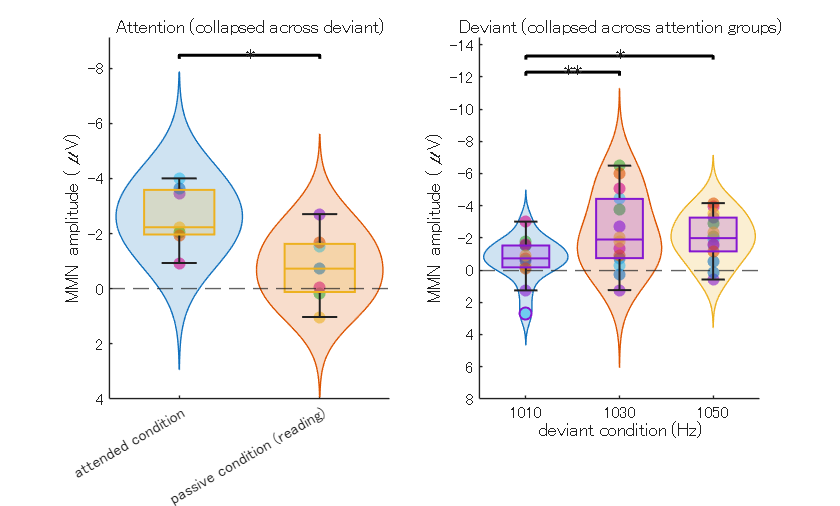

devNames = {'1010','1030','1050'};   % deviantラベル（あなたの実名に合わせて）
attNames = {'attended','passive'};

attGroup = [repmat({'attended'},7,1); repmat({'passive'},7,1)];
attGroup = categorical(attGroup, attNames);


% (A) Attention violin用：deviant で平均（被験者ごとに1点）
y_att = mean(Y, 2, 'omitnan');   % 14x1
y_att = reshape(y_att,[7,2]);

% (B) Deviant violin用：attention で平均（被験者ごとに dev 3点）
% ここでは 14名全員の値をそのまま使う（= attention 平均ではなく全体分布）
% 「attentionで平均したdeviant」の厳密版にしたい場合は下のコメント参照
y_dev = Y; % 14x3

%% ===== プロット =====
figure

% ---- subplot 1: Attention (2群) ----
subplot(1,2,1); hold on;
% violinplot は "データベクトル + グループ" 形式が使える実装が多い
violinplot(y_att);
hold on
s = swarmchart(1:1:2,y_att,'filled');
% set(s, 'SizeData', 15); % 例：20 くらい?
set(s, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeAlpha', 0.6);
boxchart(y_att)

set(gca,'XTickLabel',{'attended condition',  'passive condition (reading)'});
ylabel('MMN amplitude (\muV)');
title('Attention (collapsed across deviant)');
box off;

axis ij;

% sigstar
p_att = betweenTbl.pValue(2);
ss = sigstar({[1 2]}, p_att, 0, 'top');   % 括弧と星


% ---- subplot 2: Deviant (3水準) ----
subplot(1,2,2); hold on;
% devごとにバイオリンを並べる（列ごと）
% violinplot が行列入力に対応していればこれでOK
violinplot(y_dev);
s = swarmchart(1:1:3,y_dev,'filled');
% set(s, 'SizeData', 15); % 例：20 くらい?
set(s, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeAlpha', 0.6);
boxchart(y_dev)

axis ij;

% sigstar
groups = {[1 2],[1 3],[2 3]};
pvals  = [T2.pValue(1), T2.pValue(2), T2.pValue(4)];


ss = sigstar(groups, pvals, 0, 'top');   % 括弧と星
% ss = sigstar(groups, pvals, 0, 'auto');  % 自動（画面上）

% ss = sigstar(groups, pvals, 0, 'bottom');

% 軸・ラベル
set(gca,'XTickLabel',{'1010', '1030', '1050'});
xlabel('deviant condition (Hz)')
ylabel('MMN amplitude (\muV)');
title('Deviant (collapsed across attention groups)');
box off;

% 見やすさ：0ライン
for sp = 1:2
    subplot(1,2,sp);
    yline(0,'--');
end

## interaction plot（推奨：群平均±SE + 個人点も重ねる）

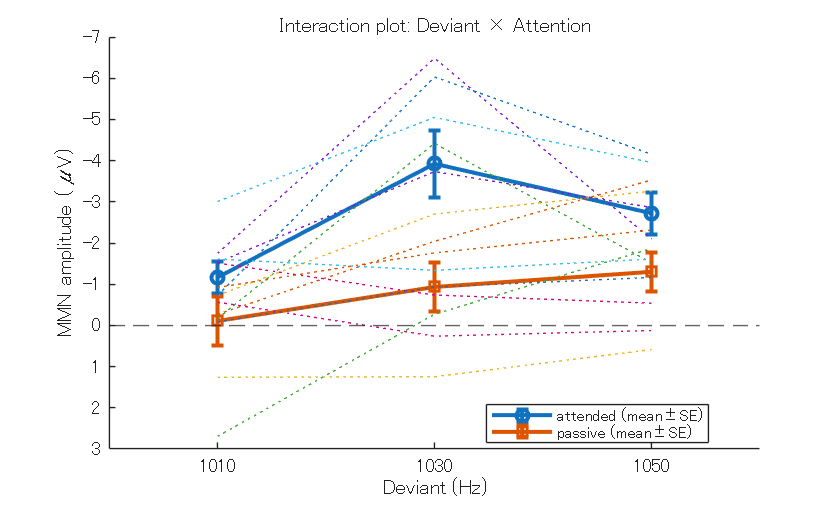

% Y: 14x3 (rows: subjects, cols: deviant 1010/1030/1050)
% Attention: 14x1 categorical ("attended","passive")
devHz = [1010 1030 1050];

isAtt = (Attention=="attended");
isPas = (Attention=="passive");

mAtt = mean(Y(isAtt,:), 1, 'omitnan');
mPas = mean(Y(isPas,:), 1, 'omitnan');

seAtt = std(Y(isAtt,:), 0, 1, 'omitnan') ./ sqrt(sum(isAtt));
sePas = std(Y(isPas,:), 0, 1, 'omitnan') ./ sqrt(sum(isPas));

figure; hold on;

% 群平均 ± SE
errorbar(devHz, mAtt, seAtt, '-o', 'LineWidth', 2);
errorbar(devHz, mPas, sePas, '-s', 'LineWidth', 2);

% 個人データ点（薄く）
for i = find(isAtt)'
    plot(devHz, Y(i,:), ':', 'HandleVisibility','off');
end

for i = find(isPas)'
    plot(devHz, Y(i,:), ':', 'HandleVisibility','off');
end
xlim([1000 1060])
set(gca,'XTick',devHz);
xlabel('Deviant (Hz)');
ylabel('MMN amplitude (\muV)');
title('Interaction plot: Deviant × Attention');
legend({'attended (mean±SE)','passive (mean±SE)'}, 'Location','best');
axis ij;  % ERP慣習（負を上にしたいならこれ）
yline(0,'--','HandleVisibility','off');
box off;
